# EXERCICIO 1

close all
clear 
clc

n=0:99

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


n1=0:49

n1 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


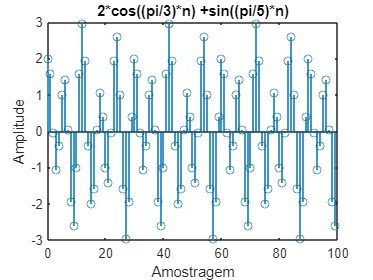


x=2*cos((pi/3)*n) +sin((pi/5)*n);

% a)
figure
stem(n,x)
xlabel("Amostragem")
ylabel("Amplitude")
title("2*cos((pi/3)*n) +sin((pi/5)*n)")


% b)

%1  
y0=indices_impares(x)

y0 =     2.0000   -0.0489   -0.4122    1.4122   -1.9511   -1.0000    2.9511   -0.4122   -1.5878    1.0489   -1.0000   -0.0489    2.5878   -1.5878   -1.9511    2.0000   -0.0489   -0.4122    1.4122   -1.9511   -1.0000    2.9511   -0.4122   -1.5878    1.0489   -1.0000   -0.0489    2.5878   -1.5878   -1.9511    2.0000   -0.0489   -0.4122    1.4122   -1.9511   -1.0000    2.9511   -0.4122   -1.5878    1.0489   -1.0000   -0.0489    2.5878   -1.5878   -1.9511    2.0000   -0.0489   -0.4122    1.4122   -1.9511


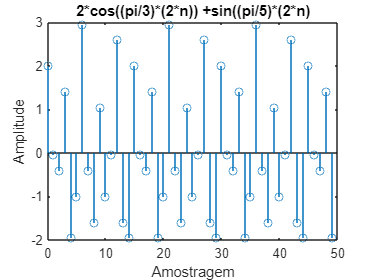

figure
stem(n1,y0)
xlabel("Amostragem")
ylabel("Amplitude")
title("2*cos((pi/3)*(2*n)) +sin((pi/5)*(2*n)")


%2
%y1=2*cos((pi/3).*(-n)) +sin((pi/5).*(-n));
y1=indices_inverter(x)

y1 =    -2.5878   -1.9511    0.0489    1.4122    1.0000   -0.4122   -1.0489   -0.0489    1.5878    2.0000    0.4122   -1.9511   -2.9511   -1.5878    1.0000    2.5878    1.9511   -0.0489   -1.4122   -1.0000    0.4122    1.0489    0.0489   -1.5878   -2.0000   -0.4122    1.9511    2.9511    1.5878   -1.0000   -2.5878   -1.9511    0.0489    1.4122    1.0000   -0.4122   -1.0489   -0.0489    1.5878    2.0000    0.4122   -1.9511   -2.9511   -1.5878    1.0000    2.5878    1.9511   -0.0489   -1.4122   -1.0000


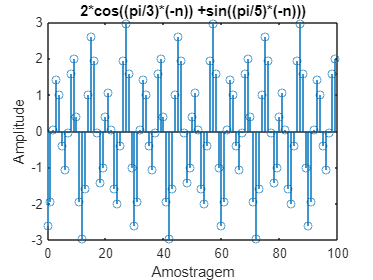

figure
stem(n,y1)
xlabel("Amostragem")
ylabel("Amplitude")
title("2*cos((pi/3)*(-n)) +sin((pi/5)*(-n)))")


%3
y2=indices_shift(x,4)

y2 =     1.5878   -0.0489   -1.0489   -0.4122    1.0000    1.4122    0.0489   -1.9511   -2.5878   -1.0000    1.5878    2.9511    1.9511   -0.4122   -2.0000   -1.5878    0.0489    1.0489    0.4122   -1.0000   -1.4122   -0.0489    1.9511    2.5878    1.0000   -1.5878   -2.9511   -1.9511    0.4122    2.0000    1.5878   -0.0489   -1.0489   -0.4122    1.0000    1.4122    0.0489   -1.9511   -2.5878   -1.0000    1.5878    2.9511    1.9511   -0.4122   -2.0000   -1.5878    0.0489    1.0489    0.4122   -1.0000


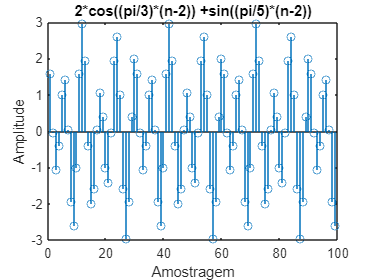

figure
stem(y2)
xlabel("Amostragem")
ylabel("Amplitude")
title("2*cos((pi/3)*(n-2)) +sin((pi/5)*(n-2))")

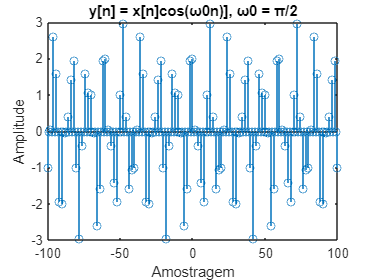


%4
n0 = -100:100;
x0 = 2*cos(pi/3*n0) + sin(pi/5*n0);
% Chamando a função para processar o sinal
y3 = cos_signal(x0);
figure
stem(n0,y3)
xlabel("Amostragem")
ylabel("Amplitude")
title("y[n] = x[n]cos(ω0n)], ω0 = π/2")

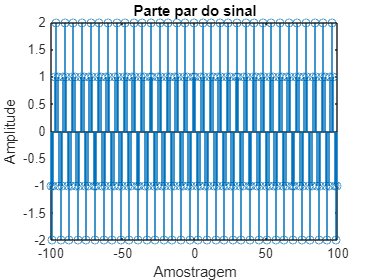


%5
[xpar, ximpar] = decompor_sinal(x0);

figure
stem(n0, xpar)
title('Parte par do sinal')
xlabel("Amostragem")
ylabel("Amplitude")

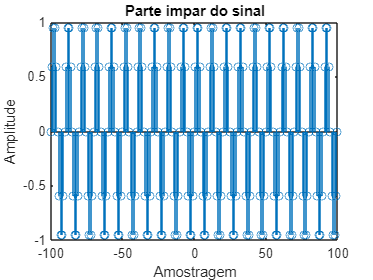

   
figure
stem(n0, ximpar)
title('Parte impar do sinal')
xlabel("Amostragem")
ylabel("Amplitude")


% c)
period = length(n0);
potencia_sinal = sinal_potencia(x, period);
% 2.469122691055866


## EXERCICIO 2

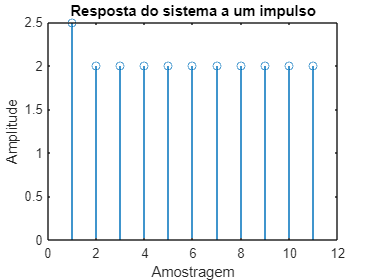

A= 0.5;
B= 2;
% y=A*x + B

% a) i
x20 = [1, zeros(1, 10)]; % impulso no instante n = 0
y20 = A*x20 + B;

figure
stem(y20); 
xlabel("Amostragem")
ylabel("Amplitude")
title('Resposta do sistema a um impulso');

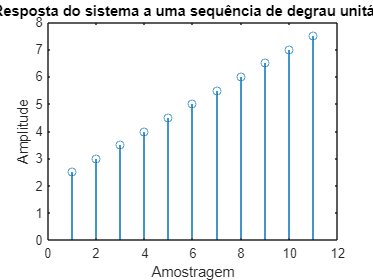


% a) ii
x21 = ones(1, 11); % degrau unitário a partir de n = 0
y21 = A*cumsum(x21) + B; % função cumsum() calcula a soma acumulada de x
figure
stem(y21); 
xlabel("Amostragem")
ylabel("Amplitude")
title('Resposta do sistema a uma sequência de degrau unitário');


% a) iii
n23 = 0:100; 
N23 = pi/2

N23 = 1.5708

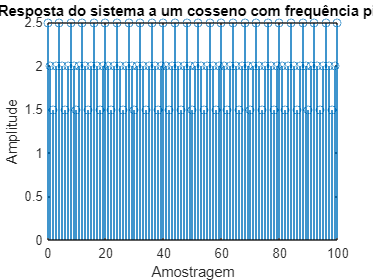

x23 = cos(N23*n23); 

y23 = A*x23 + B;

figure
stem(n23, y23); 
xlabel("Amostragem")
ylabel("Amplitude")
title('Resposta do sistema a um cosseno com frequência pi/2');

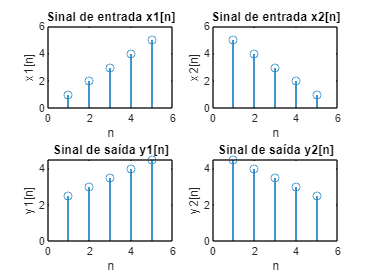


% B)
%ADITIVIDADE
x1B = [1, 2, 3, 4, 5]; % sinal 1
x2B = [5, 4, 3, 2, 1]; % sinal 2

y1B = A*x1B + B;
y2B = A*x2B + B;

figure;
subplot(2,2,1);
stem(x1B);
title('Sinal de entrada x1[n]');
xlabel('n');
ylabel('x1[n]');

subplot(2,2,2);
stem(x2B);
title('Sinal de entrada x2[n]');
xlabel('n');
ylabel('x2[n]');

subplot(2,2,3);
stem(y1B);
title('Sinal de saída y1[n]');
xlabel('n');
ylabel('y1[n]');

subplot(2,2,4);
stem(y2B);
title('Sinal de saída y2[n]');
xlabel('n');
ylabel('y2[n]');

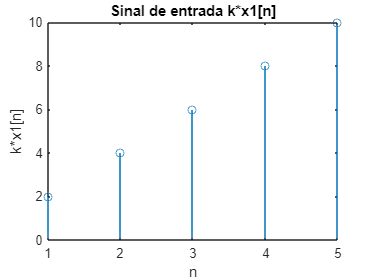


% HOMOGENEIDADE
k = 2;

y3B = A*(k*x1B) + B;

% Plot do sinal de entrada e saída
figure;
stem(k*x1B);
title('Sinal de entrada k*x1[n]');
xlabel('n');
ylabel('k*x1[n]');

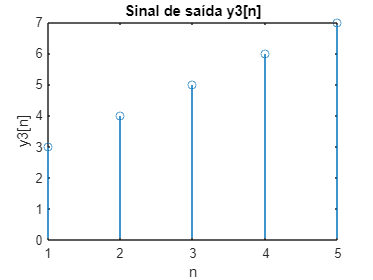

stem(y3B);
title('Sinal de saída y3[n]');
xlabel('n');
ylabel('y3[n]');

## EXERCICIO 3

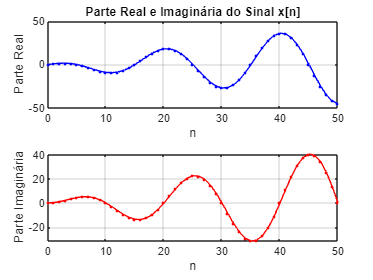

n = 0:50;
x3 = 0.9 * n .* exp(1j*(pi/10)*n);

% Parte Real e Parte Imaginária
figure;
subplot(2,1,1);
plot(n,real(x3),'b.-');
xlabel('n');
ylabel('Parte Real');
title('Parte Real e Imaginária do Sinal x[n]');
grid on;
subplot(2,1,2);
plot(n,imag(x3),'r.-');
xlabel('n');
ylabel('Parte Imaginária');
grid on;

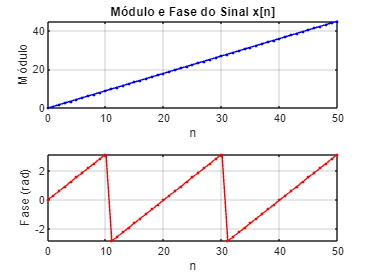


% Módulo e Fase
figure;
subplot(2,1,1);
plot(n,abs(x3),'b.-');
xlabel('n');
ylabel('Módulo');
title('Módulo e Fase do Sinal x[n]');
grid on;
subplot(2,1,2);
plot(n,angle(x3),'r.-');
xlabel('n');
ylabel('Fase (rad)');
grid on;

## EXERCICIO 4

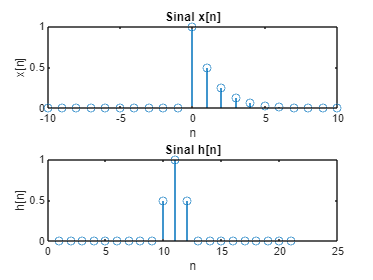

% a)
% Definição dos sinais
n4 = -10:10;
x4a = (1/2).^n4 .* (n4>=0);

h = zeros(size(n4));
h(n4 == 0) = 1;
h(n4 == -1) = 0.5;
h(n4 == 1) = 0.5;

% Plot dos sinais
figure
subplot(2,1,1);
stem(n4,x4a);
xlabel('n');
ylabel('x[n]');
title('Sinal x[n]');
subplot(2,1,2);
stem(h);
xlabel('n');
ylabel('h[n]');
title('Sinal h[n]');

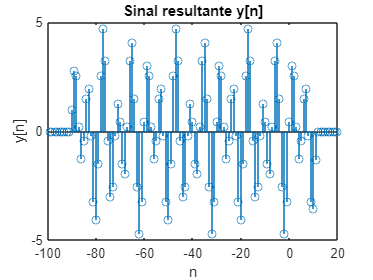


% b)
y4b = conv(x,h);
ny = -(length(x)-1):(length(h)-1);

figure
stem(ny,y4b);
xlabel('n');
ylabel('y[n]');
title('Sinal resultante y[n]');

## Funções

function comprimido = indices_impares(vetor)
    comprimido = vetor(1:2:end);
end


function reverso = indices_inverter(x)
    
    % Determina o tamanho do sinal de entrada
    N = length(x);
    
    % Inicializa o sinal de saída
    reverso = zeros(1,N);
    
    % Calcula o sinal reverso de x
    for n = 1:N
        reverso(n) = x(N-n+1);
    end   
end

function shift = indices_shift(x, n)
    shift = x(n-2:length(x));
end

function cosseno = cos_signal(x)
    w0 = pi/2;
    n = -100:100;
    % Calculando a função coseno
    cosine = cos(w0*n);
    % Multiplicando o sinal de entrada pelo coseno
    cosseno = x.*cosine;
end

function [xp, xi] = decompor_sinal(x)
    n = -100:100;
    % Calculando a parte par do sinal
    xp = (x + fliplr(x))/2;
    % Calculando a parte ímpar do sinal
    xi = (x - fliplr(x))/2;
end

function potencia = sinal_potencia(x, period)
    N = period;
    n = 0:N-1;
    x_cycle = 2*cos(pi/3*n) + sin(pi/5*n);
    potencia = (1/N) * sum(abs(x_cycle).^2);
end
